# **STANDARD** Euler technique:  

# A wheel on a pole, a **SPHERICAL joint** and gyroscopic moments 

Let's explore the classic mechanics experiment where we suspend a spinning disc (it's often a bicycle wheel) on a pole (it's often suspended from a rope).  In our case we'll use a solid wheel, and the wheel will be connected to a support tower via a "massless" rod. The support tower allows the wheel assembly to yaw($\phi$), pitch ($\theta$) and the wheel can of course spin ($\psi$).   

We'll look specificall at modelling this system using the **STANDARD** Euler equations.

The system that we'll consider is similar (but NOT identical) to the one shown in this [**youtube clip**](https://www.youtube.com/watch?v=NeXIV-wMVUk) made by Prof Lewin.  

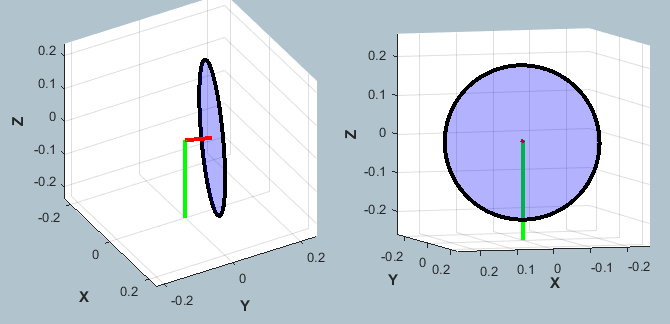 

`Bradley Horton : 24-Oct-2017, bradley.horton@mathworks.com.au`

  Change History:

- `20-Sep-2019 - `a local `cross()` function is defined as a SUBFUNCTION in this script.  This ensures consistent behavior with R2019b

## **Revision:**

Before looking at this case study, review the tutorial document `bh_CONCEPT_Passive_rots_Body_rates_Euler_rates.mlx.  `Specifically the sections:

- Review the concept of PASSIVE rotation matrices 

- An example of 3 successive PASSIVE rotations

## **Our system:**

OK, the system that we'll consider is shown below:

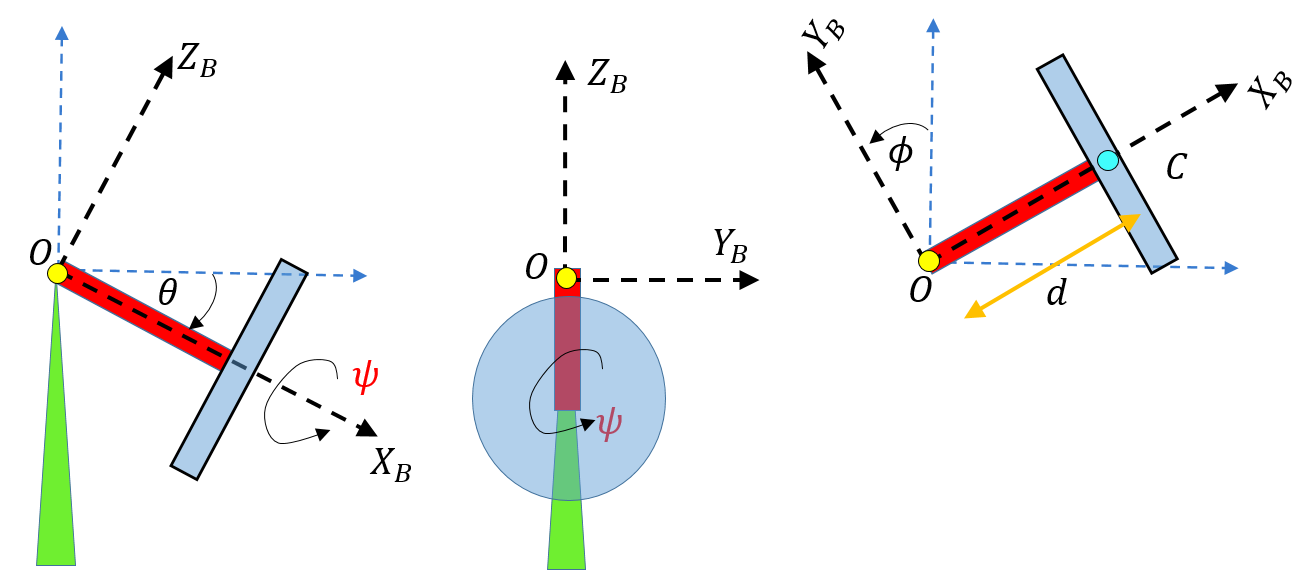

In the diagram above, note the following:

- There is 1 body which is the "combined" red ROD welded to the blue WHEEL.

- There is a "***spherical joint***" (eg: ball and socket) at the pivot point(yellow), which allows the body to rotate in X,Y,Z.

- The B-frame is attached to the body at the Pivot point *O*.

- The B-frame is RIGIDLY attached to the body -  the B-frame yaws ($\phi$) , pitches ($\theta$) and rolls ($\psi$) **with** the body .

- We'll use the term "yaw" and "precession" interchangeably.

- As stated in the introduction, the (red) rod that attaches the wheel to the pivot point *O*, is a massless rod.

The Body fixed {B}-frame can be described by the 3 Euler angles [$\phi_{1Z} , \theta_{2Y} , \psi_{3X}$] - where the ORDER of rotation is: 

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

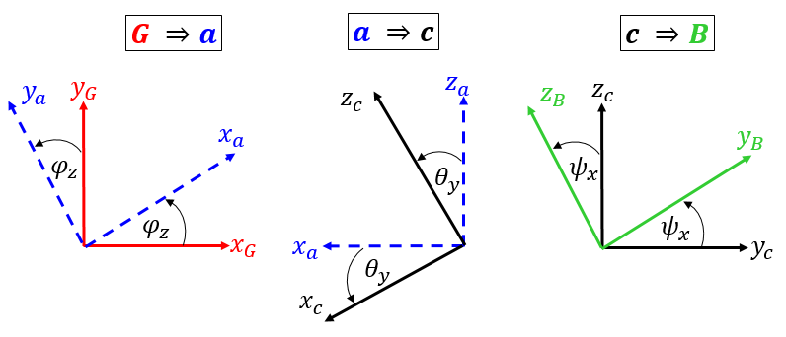

We can therefore define a Direction Cosine Matrix as:

- 
$$ {^BR_G} = R3X(\psi_x) \enspace . \enspace 
R2Y(\theta_y) \enspace . \enspace R1Z(\phi_z) .$$


The Direction Cosine Matrix $^BR_G$ can then be used to express the components of a vector in the  {B}-frame ... when we already know the vector's components in the {G}-frame, ie:

-          
$$^{B}v  = {^{B}}R_G \enspace .  {^{G}}v$$


## Define some model parameters:

- r : (m),  wheel radius

- t : (m),  wheel thickness

- m : (kg), wheel mass

- d : (m),  rod length , really it's the distance from pivot point O to the CoM of the wheel

Load some parameters needed by the Simulink models *- we'll be opening these shortly*

bh_parameters_for_models
[r,t,m,d]

ans =     0.2000    0.0200    4.0000    0.0700


And here they are:

whos   

  Name                     Size            Bytes  Class           Attributes

  EME_BUS                  1x1               395  Simulink.Bus              
  EQ                       3x1                 8  sym                       
  Ic                       3x3                72  double                    
  Ic_xx                    1x1                 8  sym                       
  Ic_xx_val                1x1                 8  double                    
  Ic_yy                    1x1                 8  sym                       
  Ic_zz                    1x1                 8  sym                       
  Io                       3x3                72  double                    
  Io_xx                    1x1                 8  sym                       
  Io_yy                    1x1                 8  sym                       
  Io_zz                    1x1                 8  sym                       
  Mb                       3x1                 8  sym                      

## The inertia matrix for solid cylinder:

Let's calculate the inertia matrix of the wheel.  First we'll determine the inertia about a frame attached to the center of mass *C* of the wheel, then we'll apply the Parallel axis theorem to calculate the inertia about the pivot point *O*. (consult the following reference for inertias of cylinders  [https://en.wikipedia.org/wiki/List_of_moments_of_inertia](https://en.wikipedia.org/wiki/List_of_moments_of_inertia)).

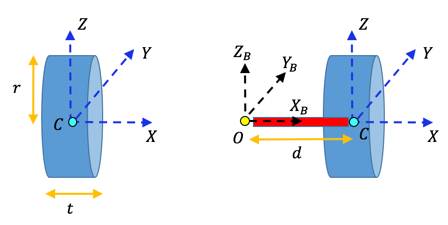

Here's the moment of inertia matrix $^B_CI$ about the cylinder's **center of mass**:

Ic = [ (m*r^2)/2,   0,                     0;
       0,           m*(3*r^2 + t^2)/12,    0;
       0,           0,                     m*(3*r^2 + t^2)/12;
     ];

% extract the spin axis Inertia term
Ic_xx_val = Ic(1,1) 

Ic_xx_val = 0.0800

And here's the cylinder's moment of inertia matrix $^B_OI$ about the pivot point "O" - note we're simply using the **Parallel axis theorem**:

dx = d;   dy = 0;   dz = 0;

Io = Ic  +  m*[  (dy^2 + dz^2),        (-dx*dy),        (-dx*dz);
                      (-dy*dx),   (dx^2 + dz^2),        (-dy*dz);
                      (-dz*dx),        (-dz*dy),   (dx^2 + dy^2);  ];                  

Note how the Inertia matrix is still (as expected) a diagonal matrix

% echo the Inertia matrix
Io

Io =     0.0800         0         0
         0    0.0597         0
         0         0    0.0597


## The Applied system Torques:

The wheel is subjected to a gravity TORQUE due to the wheel's mass and the offset distance "*d *" to the pivot point *O. * We can express this Torque vector in components of the {B}-frame, as the ***CROSS PRODUCT*** of the arm length and the applied force:

- $^B_O\tau_{GRAVITY} \enspace = \enspace ^Br \enspace \times \enspace ^B\overrightarrow{F_{GRAV}}
 
}$  =  $ \enspace ^Br \enspace \times \enspace (^BR_G \enspace . \enspace ^G\overrightarrow{F_{GRAV}})
 
}$

There is also a 2nd torque applied to the WHEEL ... and this is the torque needed to either accelerate of decelerate the spin of the wheel about the body fixed X-axis, ie:

- $^B_O\tau_{SPIN} \enspace = \pmatrix{
^B_CI_{xx} \enspace . \enspace \dot{\Omega}_x \cr
0 \cr
0

}$ where $\dot{\Omega}_x$ is the desired spin acceleration of the wheel.

So the total torque action on the body and taken about the pivot point "O" is:

- 
$$^B_OM = {^B_O\tau_{SPIN}} \enspace + \enspace {^B_O\tau_{GRAVITY}}$$


## ** The Physics of the system:**

The equations of motion for this system are defined by the **STANDARD Euler moment equation** (SEME) for a rigid body - Note that all terms are expressed in components of the body fixed {B}-frame.

- 
$$^B_OM  = \enspace 
^B_OI.\dot{\omega} + \omega \times (^B_OI.\omega) $$


 Let's consider the ***specific case*** where (this corresponds to our "**Wheel on a pole**" system):

-  $^B_OI = 
\pmatrix{
^B_OI_{xx} & 0 & 0 \cr
0 & ^B_OI_{yy} & 0 \cr
0 & 0 & ^B_OI_{zz} \cr
}$, $\omega = 
\pmatrix{
\omega_x \cr
\omega_y \cr
\omega_z
}$ where $\omega$ is the angular velocity of the B-frame.

% define some symbolic variables
syms Ic_xx Ic_yy Ic_zz                     real 
syms Io_xx Io_yy Io_zz                     real 
syms omega_x omega_y omega_z               real 
syms omega_dot_x omega_dot_y omega_dot_z   real 

Here's our $^B_OI$:

soI          = [ Io_xx,     0,     0;
                   0,   Io_yy,     0;
                   0,     0,   Io_zz];               

Here's our $\omega$ and $\dot{\omega}$:    

 sw         =  [omega_x;        omega_y;       omega_z];
 sw_DOT     =  [omega_dot_x;    omega_dot_y;   omega_dot_z]; 

If we now focus on the RHS of our equation of motion, ie:   $^B_OI.\dot{\omega} 
\enspace
+
\enspace
 \omega \times (^B_OI.\omega) $ ,  we get

tmp_RHS = soI*sw_DOT + cross(sw, soI*sw)

$$tmp\_RHS = \left(\begin{array}{c} {\mathrm{Io}}_{\mathrm{xx}}\,{\dot{\omega }}_{x}-{\mathrm{Io}}_{\mathrm{yy}}\,\omega_{y}\,\omega_{z}+{\mathrm{Io}}_{\mathrm{zz}}\,\omega_{y}\,\omega_{z}\\ {\mathrm{Io}}_{\mathrm{yy}}\,{\dot{\omega }}_{y}+{\mathrm{Io}}_{\mathrm{xx}}\,\omega_{x}\,\omega_{z}-{\mathrm{Io}}_{\mathrm{zz}}\,\omega_{x}\,\omega_{z}\\ {\mathrm{Io}}_{\mathrm{zz}}\,{\dot{\omega }}_{z}-{\mathrm{Io}}_{\mathrm{xx}}\,\omega_{x}\,\omega_{y}+{\mathrm{Io}}_{\mathrm{yy}}\,\omega_{x}\,\omega_{y} \end{array}\right)$$

So our system moment equation can now be written as:

- 
$$^B_OM = ({^B_O\tau_{SPIN}} \enspace + \enspace {^B_O\tau_{GRAVITY}}) \enspace = \enspace $$
  
$$ \pmatrix{
^B_OI_{xx} \thinspace . \thinspace \dot{\omega_x} + \omega_y\omega_z \thinspace. \thinspace (^B_OI_{zz}-^B_OI_{yy}) 
\cr
^B_OI_{yy} \thinspace . \thinspace \dot{\omega_y} + \omega_x\omega_z \thinspace. \thinspace (^B_OI_{xx}-^B_OI_{zz})
\cr
^B_OI_{zz} \thinspace . \thinspace \dot{\omega_z} + \omega_x\omega_y \thinspace. \thinspace (^B_OI_{yy}-^B_OI_{xx})
}$$


Recalling the symmetry of our system, ie:  $^B_OI_{zz} \enspace = \enspace ^B_OI_{yy}$we can simplify the above equation to:

- 
$$^B_OM = ({^B_O\tau_{SPIN}} \enspace + \enspace {^B_O\tau_{GRAVITY}}) \enspace = \enspace $$
 
$$ \pmatrix{
^B_OI_{xx} \thinspace . \thinspace \dot{\omega_x} 
\cr
^B_OI_{yy} \thinspace . \thinspace \dot{\omega_y} + \omega_x\omega_z \thinspace. \thinspace (^B_OI_{xx}-^B_OI_{yy})
\cr
^B_OI_{zz} \thinspace . \thinspace \dot{\omega_z} - \omega_x\omega_y \thinspace. \thinspace (^B_OI_{xx}-^B_OI_{yy})
}$$


And we can move some terms from the RHS to the LHS:

- $^B_OM -  $ $ \pmatrix{
0
\cr
 \omega_x\omega_z \thinspace. \thinspace (^B_OI_{xx}-^B_OI_{yy})
\cr
-1. \omega_x\omega_y \thinspace. \thinspace (^B_OI_{xx}-^B_OI_{yy})
}$ = $ \pmatrix{
^B_OI_{xx} \thinspace . \thinspace \dot{\omega_x} 
\cr
^B_OI_{yy} \thinspace . \thinspace \dot{\omega_y} 
\cr
^B_OI_{zz} \thinspace . \thinspace \dot{\omega_z} 
}$

Tidy up:

clear Ic_xx Ic_yy Ic_zz  
clear Io_xx Io_yy Io_zz 
clear omega_x omega_y omega_z  omega_dot_x omega_dot_y omega_dot_z

## The Simulink model:

Our system equation of motion is a beautiful thing ..... but how do we make this mathematics come alive?  How do we get confidence that what we see in the real world (... and on youtube) is explained by our maths ? Well, the easiest way to solve our moment equations is to model/represent these equations in Simulink.  Open and explore the following Simulink model `<bh_wheel_dynamics_model_SEME>` .  

        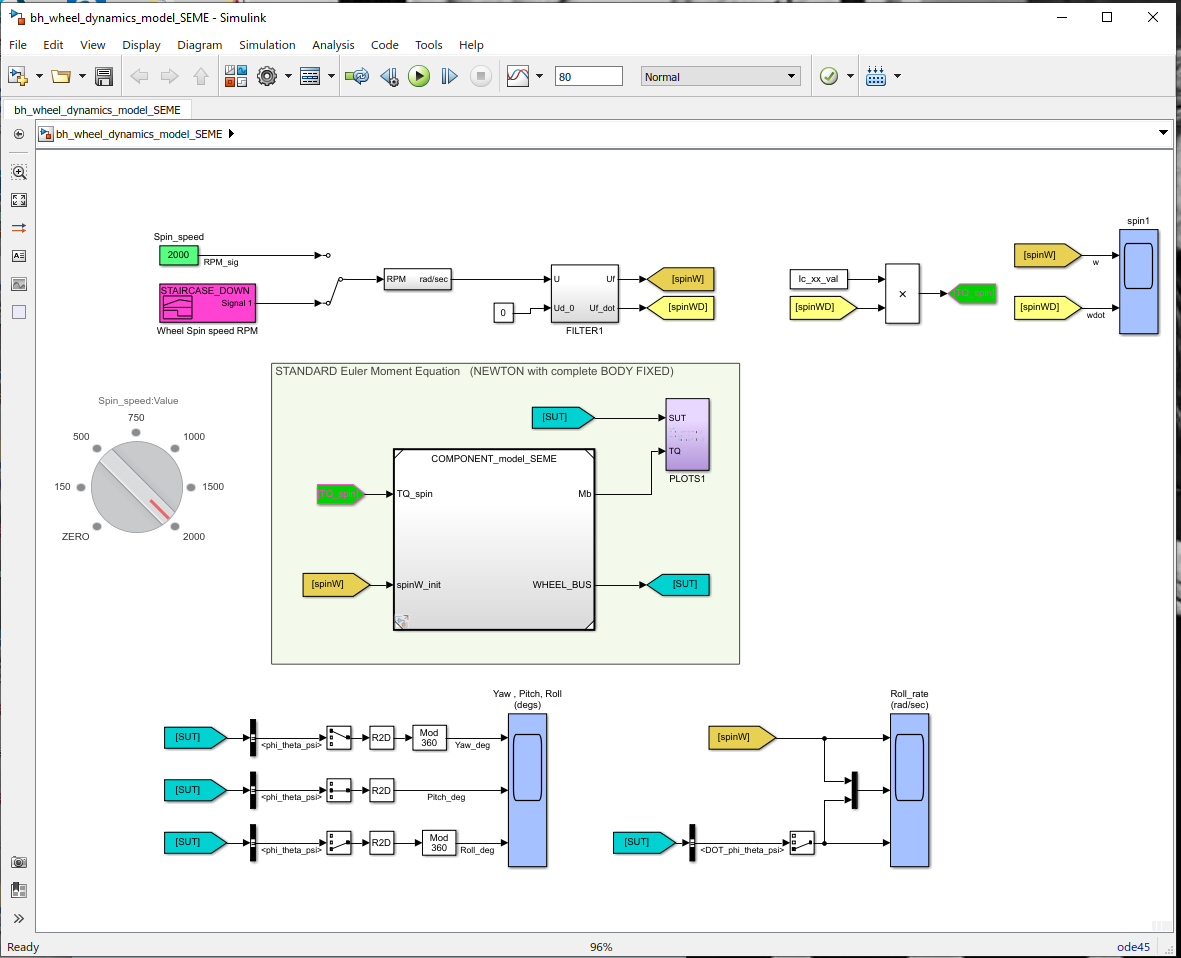

Open and run the Simulink model:

%open_system('bh_wheel_dynamics_model_SEME')                   

**SOMETHING to**** TRY: ** Interact with the wheel spin speed block(shown below) and observe the system response for the different wheel spin speeds : 0, 150 and 2000 RPM. 

   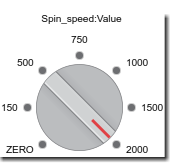         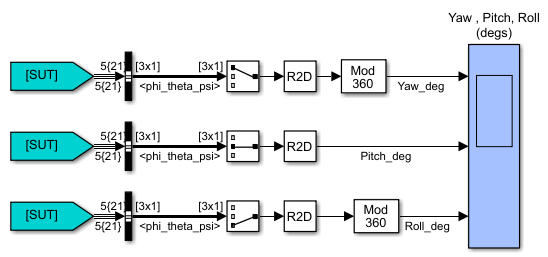         

When you do this, observe the time traces of the Yaw (precession) angle ($\phi$) and the Pitch angle ($\theta$).  Note the following:

- when $\Omega=0 \enspace RPM:$ the wheel assembly acts like a pendulum and pitches from $0 \longrightarrow 180$ degrees (we have NO friction at the pivot point *O*)

- when $\Omega=150 \enspace RPM:$ the wheel assembly precesses (ie: rotates about the inertial $Z$axis) and takes about 2.97 seconds to do 1 revolution about the $Z$axis. The wheel also pitches from $0 \longrightarrow 12$ degrees.

- when $\Omega=2000 \enspace RPM:$ the wheel assembly precesses very slowly (it takes about 38 seconds for 1 revolution about the inertial $Z$axis), and it only pitches about  $ 0.06 $ degrees. 

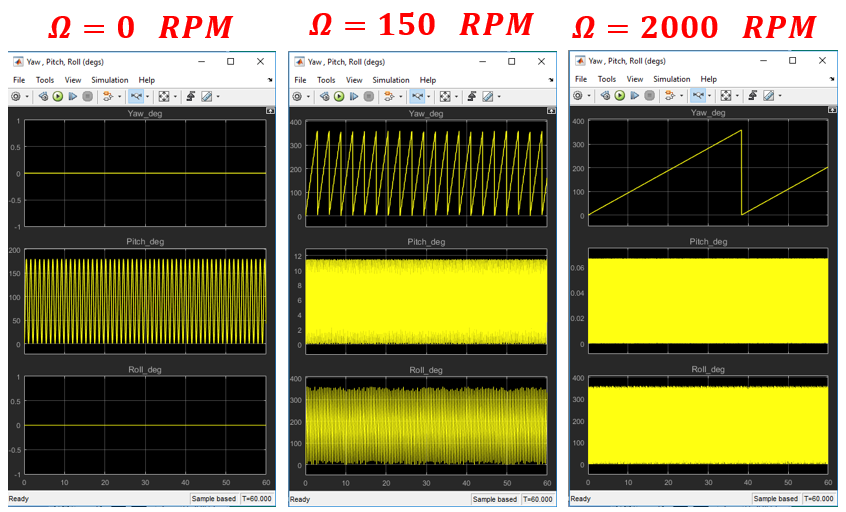

## What happens when ......

If we increase the TORQUE on the wheel, what do you think will happen? We can increase the torque by making the offset distance "*d*" bigger. If we do increase the torque, which of the following do you think will happen:

- The yaw rate (or precession) will decrease.  

- The yaw rate (or precession) will INcrease.   

**SOMETHING to TRY: ** Consider the scenario where $\Omega=2000 $ RPM and we double the size of  "*d*".  Did you get the result that you expected ?

**So ?**

From Newton's laws we were given the fundamental equations that describe the physics of this system:

- 
$$^B_OM  = \enspace 
^B_OI.\dot{\omega} + \omega \times (^B_OI.\omega) $$


During this session we:

- We were able to solve these equations(using Simuink) and saw how the mathematical model behaved just like Prof Lewin's  [**youtube clip**](https://www.youtube.com/watch?v=NeXIV-wMVUk).

- We saw that the gyroscopic moments that keep the wheel "floating" are dependent on the wheel's spin velocity ($\Omega$) and the wheel's precession (or YAW) angular velocity ($\omega_z$) .  And if you make either of these two terms ZERO, then the system just behaves like a pendulum.

So there you have it.  

# **APPENDIX_A:**  Here's another way to model this system.

Review the model called <`bh_wheel_dynamics_COMPARE_hand_SEME_to_simscape`>.  Here we've modelled the same "wheel on a pole" system ... but we've used Simscape to do it.  Simscape uses model building elements such as "joints, bodies, sensors":   And it has a great visualization tool called *Mechanics Explorer* to help you view your assembled machine.

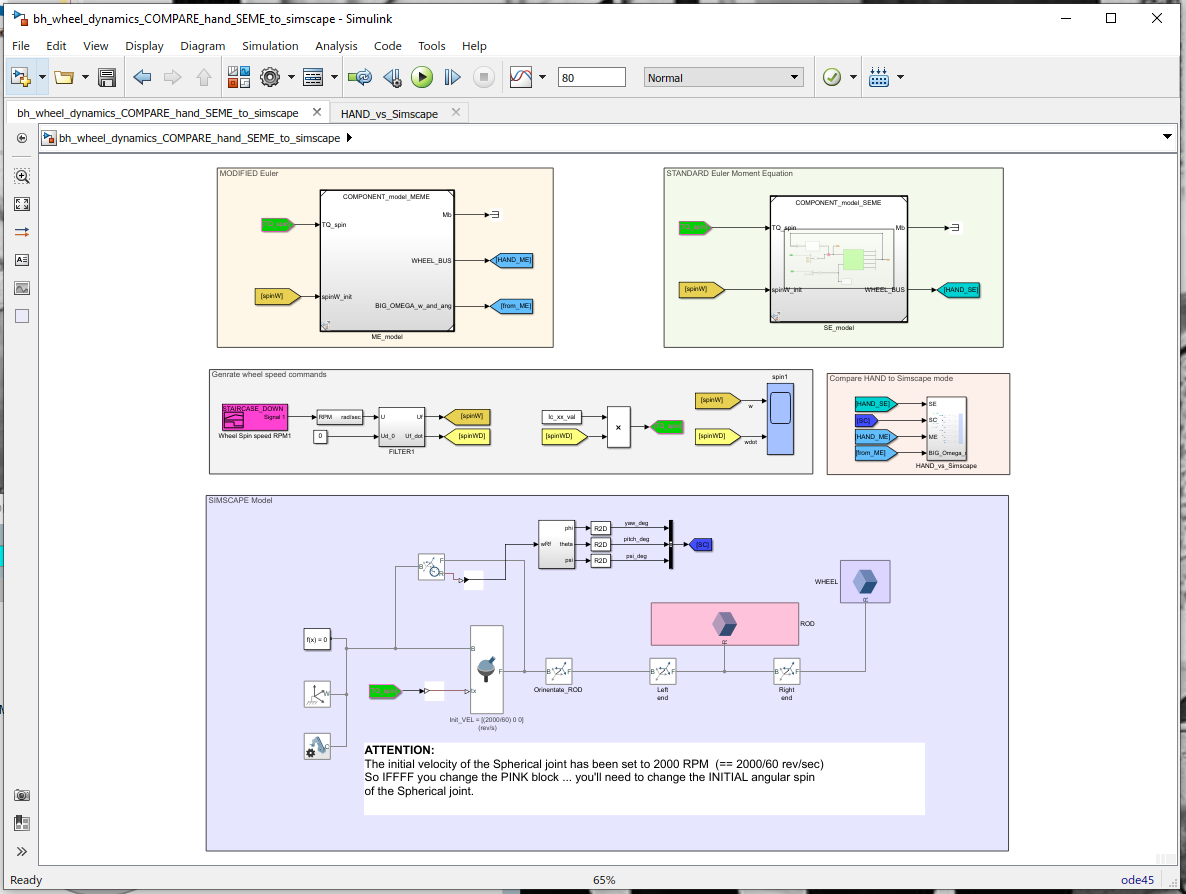

# Local functions only beyond this point:

The vector cross product

function c = cross(a,b)

    c1 = a(2).*b(3)-a(3).*b(2);
    c2 = a(3).*b(1)-a(1).*b(3);
    c3 = a(1).*b(2)-a(2).*b(1);

    c  = [c1;c2;c3]; 

end